type sobel

% edgeImage = sobel(originalImage, threshold)
% Sobel edge detection. Given a normalized image (with double values)
% return an image where the edges are detected w.r.t. threshold value.
function edgeImage = sobel(originalImage, threshold) %#codegen
assert(all(size(originalImage) <= [2048 2048]));
assert(isa(originalImage, 'double'));
assert(isa(threshold, 'double'));

k = [1 2 1; 0 0 0; -1 -2 -1];
H = conv2(double(originalImage),k, 'same');
V = conv2(double(originalImage),k','same');
E = sqrt(H.*H + V.*V);
edgeImage = uint8((E > threshold) * 255);


codegen sobel

Code generation successful.



**Read the image and resize to 1024  x 1024**

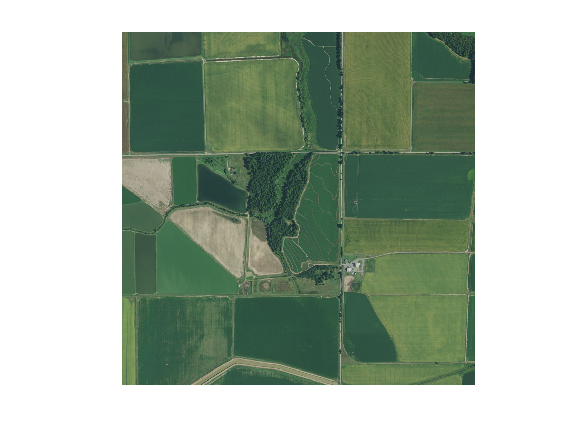

im = imread('field.jpg');
im = imresize(im, 0.50);
imshow(im);

**Convert to Gray Scale Image**

Grayim = (0.2989 * double(im(:,:,1)) + 0.5870 * double(im(:,:,2)) + 0.1140 * double(im(:,:,3)))/255;
Grayim2 = rgb2gray(im)

Grayim2 = 1024×1024 uint8 matrix
   106   104   102   103   106   100    95   102   105   110   115   111   108    99   119   104    91    90    84    95   105    96    95    87    79    85    86    86    86    87    87    87    89    89    90    91    91    91    91    91    91    91    91    91    91    91    91    91    91    90
   105   102   102   106   100    95    96    98   109   110   114   112   109   101   117   103    93    92    84    94   104    93    92    88    78    84    85    86    87    87    88    88    89    89    90    91    91    91    91    91    91    91    91    91    91    91    91    91    91    90
   104   102   101   103   101   101    95   101   111   113   112   113   113   103   112   107    95    91    85    93   104    92    90    89    78    84    85    86    87    88    88    89    89    89    90    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91
   101   104   102    98   102   103    93   102   109   112   1

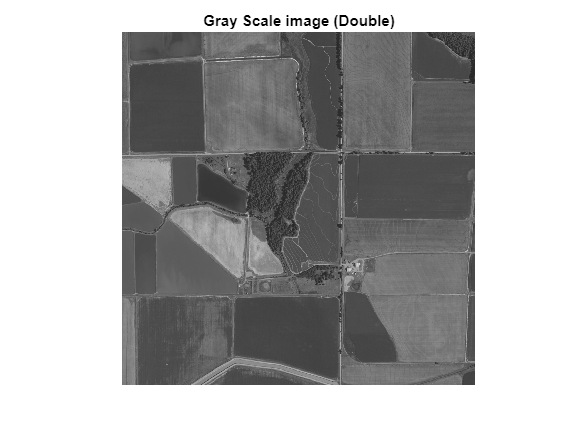

imshow(Grayim), title("Gray Scale image (Double)");

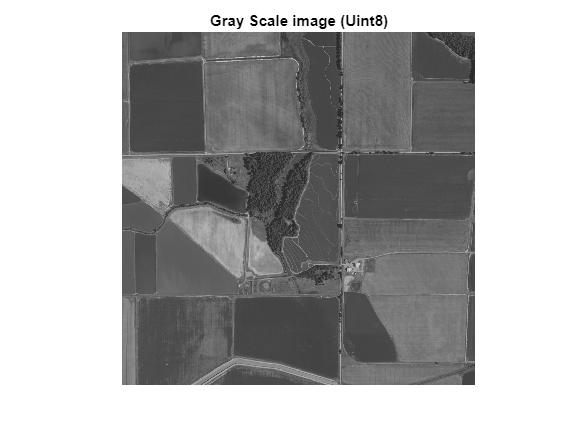

imshow(Grayim2), title("Gray Scale image (Uint8)");

**Run the MEX Function (The Sobel Filter)    **

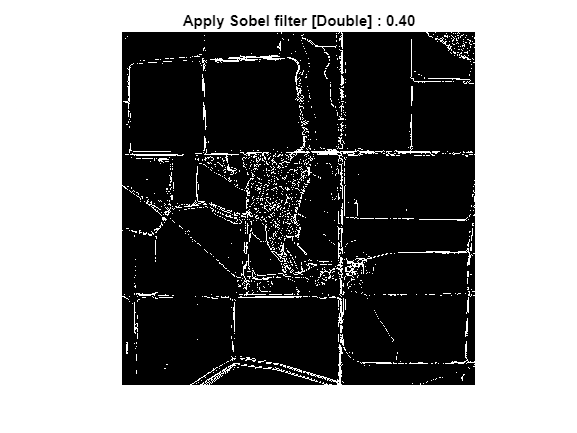

Sobel_Image_040 = sobel_mex(Grayim, 0.4);
imshow(Sobel_Image_040), title("Apply Sobel filter [Double] : 0.40");

**Apply the sobel filter**

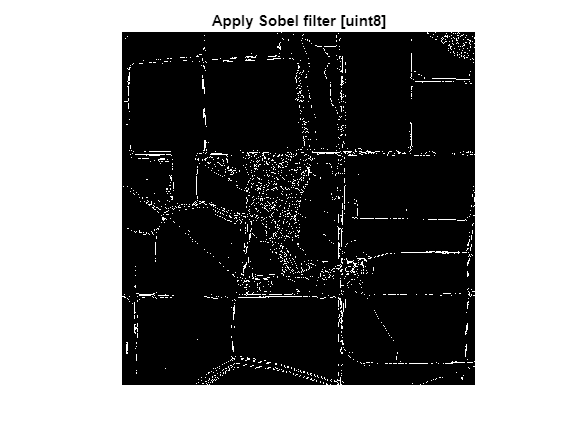

Sobel_Image_040_b = edge(Grayim2, 'sobel');
imshow(Sobel_Image_040_b), title("Apply Sobel filter [uint8]");

**Apply repmat [replicate and tile array] --> Gain more contrast**

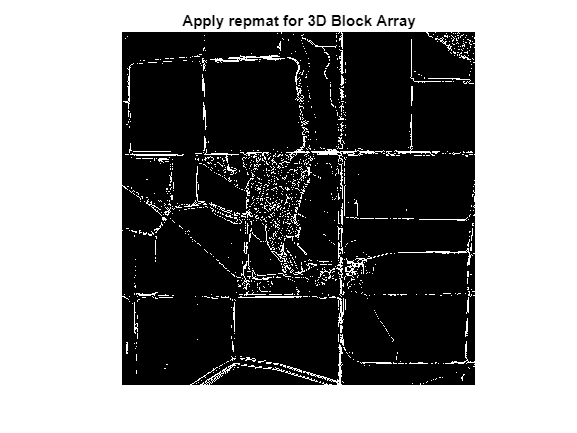

im3 = repmat(Sobel_Image_040, [1 1 3]);
imshow(im3),title("Apply repmat for 3D Block Array");

**Apply Canny filter**

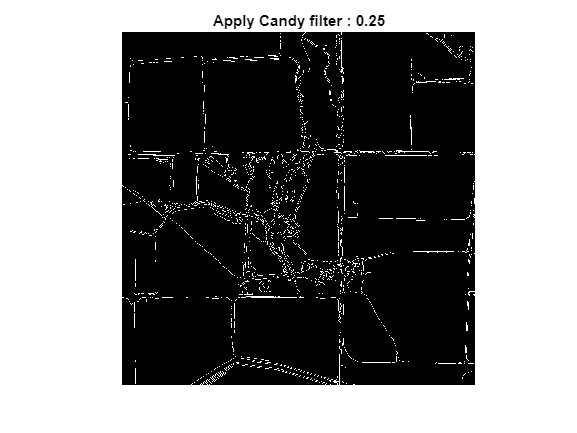

Canny_image1 = edge(Grayim2, 'canny', 0.25);
imshow(Canny_image1), title("Apply Candy filter : 0.25");

**Apply Laplacian of Gaussian**

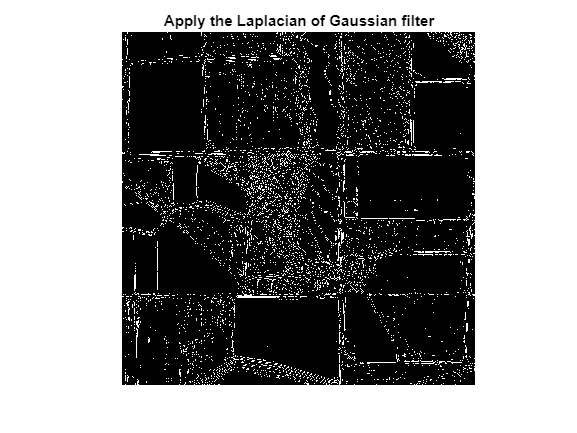

log_image1 = edge(Grayim2, 'log');
imshow(log_image1), title("Apply the Laplacian of Gaussian filter");

**HOUGH transform **

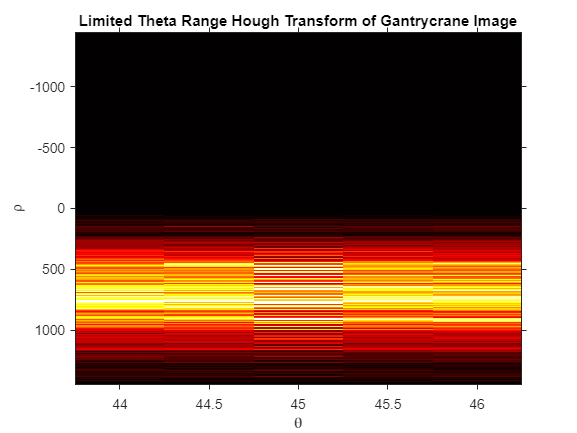

[H,T,R] = hough(Canny_image1,'Theta',44:0.5:46);
figure
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
   'InitialMagnification','fit');
title('Limited Theta Range Hough Transform of Gantrycrane Image');
xlabel('\theta')
ylabel('\rho');
axis on, axis normal;
colormap(gca,hot)